# Evaluación ejercicio 2

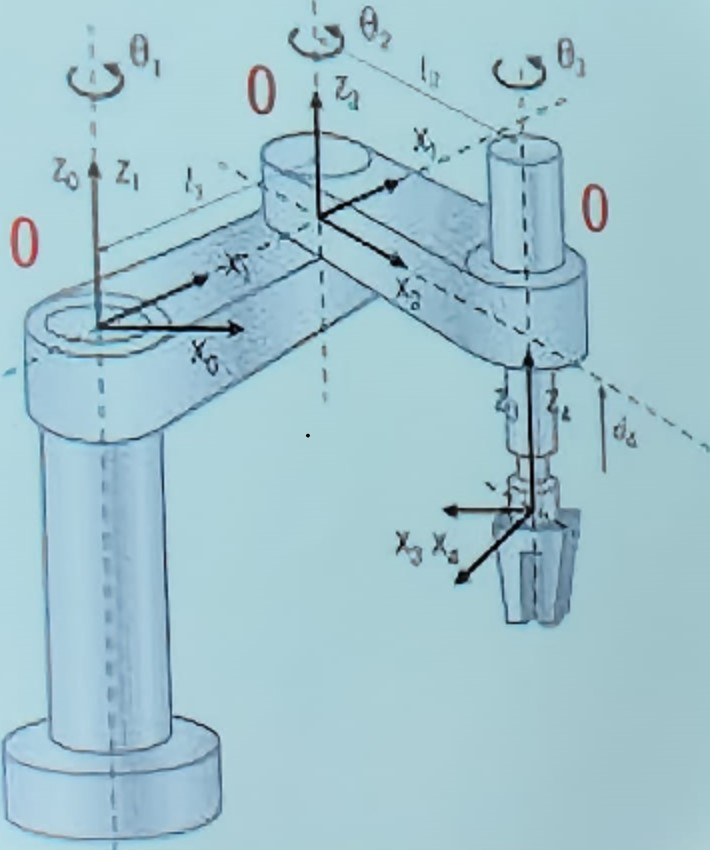

Calcula el vector de las velocidades lineales y angulares para el robot mostrado:

%Limpieza de pantalla
clear all
close all
clc

%Declaración de variables simbólicas
syms th1(t) th2(t) th3(t) t l1 l2 l3

%Configuración del robot, 0 para junta rotacional, 1 para junta prismática
RP=[0 0 0];

%Creamos el vector de coordenadas articulares
Q= [th1, th2, th3];
%disp('Coordenadas generalizadas');
%pretty (Q);

%Creamos el vector de velocidades generalizadas
Qp= diff(Q, t);
%disp('Velocidades generalizadas');
%pretty (Qp);
%Número de grado de libertad del robot
GDL= size(RP,2);
GDL_str= num2str(GDL);

Para estas articulaciones tenía la idea que no era necesario una rotación para llegar de la articulación a la 2 y solo se necesitaría una rotación de 180° en x para la articulación 2 a la 3, sin embargo por un error de matlab no pude llegar al resultado deseado este el ultimo codigo que me permitió correr pero no tiene la idea que yo quería emplear:


%Articulación 1 
%Posición de la articulación 1 respecto a 0
P(:,:,1)= [0;0;l1];
%Matriz de rotación de la junta 1 respecto a 0.... 
R(:,:,1)= [0    0           0;
           0    cos(th1)   -sin(th1);
           0    sin(th1)    cos(th1)];



%Articulación 2
%Posición de la articulación 2 respecto a 1
P(:,:,2)= [l2*cos(th2); l2*sin(th2);0];
%Matriz de rotación de la junta 1 respecto a 0
R(:,:,2)= [0    0           0;
           0    cos(th2)   -sin(th2);
           0    sin(th2)    cos(th2)];



%Articulación 3 
%Posición de la articulación 3 respecto a 2
P(:,:,3)= [l3*cos(th3); l3*sin(th3);0];
%Matriz de rotación de la junta 3 respecto a 2  0º
R(:,:,3)= [0    0           0;
           0    cos(th3)   -sin(th3);
           0    sin(th3)    cos(th3)];

%Creamos un vector de ceros
Vector_Zeros= zeros(1, 3);

%Inicializamos las matrices de transformación Homogénea locales
A(:,:,GDL)=simplify([R(:,:,GDL) P(:,:,GDL); Vector_Zeros 1]);
%Inicializamos las matrices de transformación Homogénea globales
T(:,:,GDL)=simplify([R(:,:,GDL) P(:,:,GDL); Vector_Zeros 1]);
%Inicializamos las posiciones vistas desde el marco de referencia inercial
PO(:,:,GDL)= P(:,:,GDL); 
%Inicializamos las matrices de rotación vistas desde el marco de referencia inercial
RO(:,:,GDL)= R(:,:,GDL); 


for i = 1:GDL
    i_str= num2str(i);
   %disp(strcat('Matriz de Transformación local A', i_str));
    A(:,:,i)=simplify([R(:,:,i) P(:,:,i); Vector_Zeros 1]);
   %pretty (A(:,:,i));

   %Globales
    try
       T(:,:,i)= T(:,:,i-1)*A(:,:,i);
    catch
       T(:,:,i)= A(:,:,i);
    end
    disp(strcat('Matriz de Transformación global T', i_str));
    T(:,:,i)= simplify(T(:,:,i));
    pretty(T(:,:,i))

    RO(:,:,i)= T(1:3,1:3,i);
    PO(:,:,i)= T(1:3,4,i);
    %pretty(RO(:,:,i));
    %pretty(PO(:,:,i));
end

Matriz de Transformación global T1


/ 0,      0,            0,       0 \
|                                  |
| 0, cos(th1(t)), -sin(th1(t)),  0 |
|                                  |
| 0, sin(th1(t)),  cos(th1(t)), l1 |
|                                  |
\ 0,      0,            0,       1 /



Matriz de Transformación global T2


/ 0,  0,  0,                 0                \
|                                             |
| 0, #2, -#1,    l2 cos(th1(t)) sin(th2(t))   |
|                                             |
| 0, #1,  #2, l1 + l2 sin(th1(t)) sin(th2(t)) |
|                                             |
\ 0,  0,  0,                 1                /

where

   #1 == sin(th1(t) + th2(t))

   #2 == cos(th1(t) + th2(t))




Matriz de Transformación global T3


/ 0,    0,        0,                                0                            \
|                                                                                |
| 0, cos(#1), -sin(#1),    l2 cos(th1(t)) sin(th2(t)) + l3 sin(th3(t)) cos(#2)   |
|                                                                                |
| 0, sin(#1),  cos(#1), l1 + l2 sin(th1(t)) sin(th2(t)) + l3 sin(th3(t)) sin(#2) |
|                                                                                |
\ 0,    0,        0,                                1                            /

where

   #1 == th1(t) + th2(t) + th3(t)

   #2 == th1(t) + th2(t)






%Calculamos el jacobiano lineal de forma diferencial
%disp('Jacobiano lineal obtenido de forma diferencial');
%Derivadas parciales de x respecto a th1 y th2
Jv11= functionalDerivative(PO(1,1,GDL), th1);
Jv12= functionalDerivative(PO(1,1,GDL), th2);
Jv13= functionalDerivative(PO(1,1,GDL), th3);
%Derivadas parciales de y respecto a th1 y th2
Jv21= functionalDerivative(PO(2,1,GDL), th1);
Jv22= functionalDerivative(PO(2,1,GDL), th2);
Jv23= functionalDerivative(PO(2,1,GDL), th3);
%Derivadas parciales de z respecto a th1 y th2
Jv31= functionalDerivative(PO(3,1,GDL), th1);
Jv32= functionalDerivative(PO(3,1,GDL), th2);
Jv33= functionalDerivative(PO(3,1,GDL), th3);

%Creamos la matríz del Jacobiano lineal
jv_d=simplify([Jv11 Jv12 Jv13;
              Jv21 Jv22 Jv23;
              Jv31 Jv32 Jv33]);
%pretty(jv_d);


%Calculamos el jacobiano lineal de forma analítica
Jv_a(:,GDL)=PO(:,:,GDL);
Jw_a(:,GDL)=PO(:,:,GDL);

for k= 1:GDL
    if RP(k)==0 
       %Para las juntas de revolución
        try
            Jv_a(:,k)= cross(RO(:,3,k-1), PO(:,:,GDL)-PO(:,:,k-1));
            Jw_a(:,k)= RO(:,3,k-1);
        catch
            Jv_a(:,k)= cross([0,0,1], PO(:,:,GDL));%Matriz de rotación de 0 con respecto a 0 es la Matriz Identidad, la posición previa tambien será 0
            Jw_a(:,k)=[0,0,1];%Si no hay matriz de rotación previa se obtiene la Matriz identidad
         end
     else
%         %Para las juntas prismáticas
        try
            Jv_a(:,k)= RO(:,3,k-1);
        catch
            Jv_a(:,k)=[0,0,1];
        end
            Jw_a(:,k)=[0,0,0];
     end
 end    

Jv_a= simplify (Jv_a);
Jw_a= simplify (Jw_a);
%disp('Jacobiano lineal obtenido de forma analítica');
%pretty (Jv_a);
%disp('Jacobiano ángular obtenido de forma analítica');
%pretty (Jw_a);


disp('Velocidad lineal obtenida mediante el Jacobiano lineal');

Velocidad lineal obtenida mediante el Jacobiano lineal


V=simplify (Jv_a*Qp');
pretty(V);

/   _________                                                                      _________                                                    _________             \
|    d                                                                              d                                                            d                    |
| - -- th1(t) (l2 cos(th1(t)) sin(th2(t)) + l3 sin(th3(t)) cos(th1(t) + th2(t))) - -- th2(t) (l2 sin(th2(t)) + l3 cos(th2(t)) sin(th3(t))) - l3 -- th3(t) sin(th3(t)) |
|   dt                                                                             dt                                                           dt                    |
|                                                                                                                                                                     |
|                                                                                  0                                                                            

disp('Velocidad angular obtenida mediante el Jacobiano angular');

Velocidad angular obtenida mediante el Jacobiano angular


W=simplify (Jw_a*Qp');
    pretty(W);

/                                  0                                 \
|                                                                    |
|        _________                        _________                  |
|         d                                d                         |
|      - -- th3(t) sin(th1(t) + th2(t)) - -- th2(t) sin(th1(t))      |
|        dt                               dt                         |
|                                                                    |
| _________   _________                        _________             |
|  d           d                                d                    |
| -- th1(t) + -- th3(t) cos(th1(t) + th2(t)) + -- th2(t) cos(th1(t)) |
\ dt          dt                               dt                    /

